Anant Mital 

Student # 272484

## Problem 1

a)

syms y(t); 
res = dsolve(diff(y, t) == -10*y + sin(100*t) -cos(100*t), y(0) == 1);
ye = matlabFunction(res);


b)

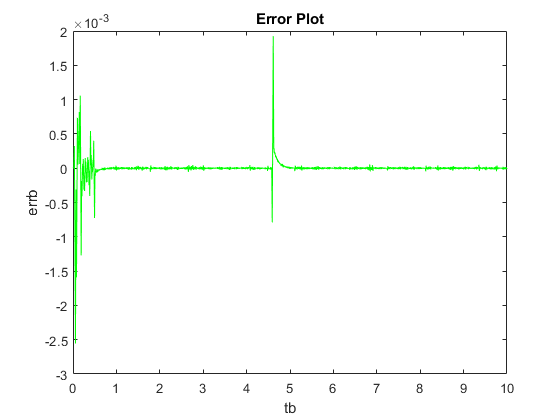

f = @(t, y) -10*y + sin(100*t) -cos(100*t);
[tb, yb] = ode45(f, [0, 10], 1);
errb = ye(tb) - yb;
figure;
plot(tb,errb,'Color','g');
title('Error Plot');
xlabel('tb');
ylabel('errb');


maxerrb = max(abs(errb));

c)

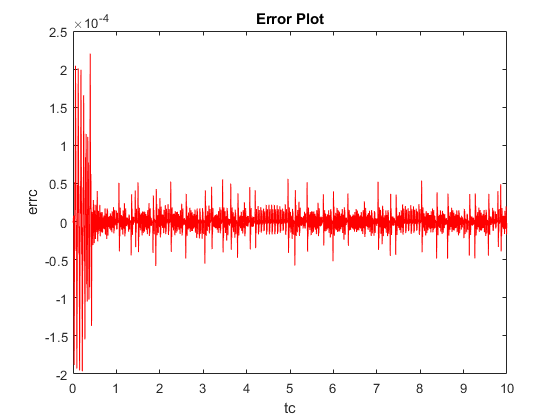

[tc, yc] = ode45(f, [0, 10], 1,odeset('MaxStep',pi/100));
errc = ye(tc) - yc;
figure;
plot(tc,errc,'Color','r');
title('Error Plot');
xlabel('tc');
ylabel('errc');

maxerrc = max(abs(errc));

d)

reltol = 1e-10;
abstol = 1e-11;
opts = odeset('RelTol',reltol,'AbsTol',abstol);
[td, yd] = ode45(f, [0, 10], 1,opts);
errd = ye(td) - yd;
maxerrd = max(abs(errd))

maxerrd = 1.0661e-09

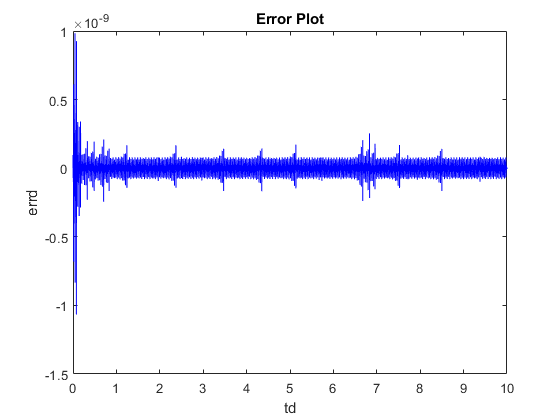

figure;
plot(td,errd,'Color','b');
title('Error Plot');
xlabel('td');
ylabel('errd');